data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]


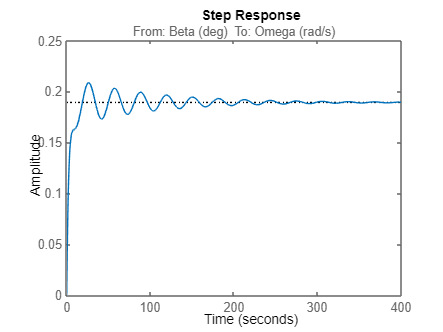


FWT = data.FWT;
A=data.A;
B=data.B;
C=data.C;
D=data.D;
%print(data)
sys1 = ss(A,B,C,D);

step(-FWT(1,1));

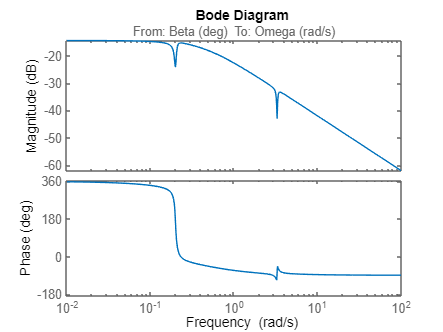

bode(-FWT(1,1));

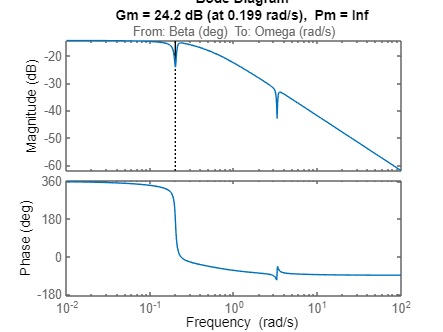

margin(-FWT(1,1)); 

pzplot(-FWT(1,1));

stepinfo(-FWT(1,1));


% PID controller
Plant = -FWT(1,1);
Kp = 400;
Ki = 50.2;
Kd = 400;
Tf = 0.06;
C = pid(Kp,Ki,Kd,Tf)

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 400, Ki = 50.2, Kd = 400, Tf = 0.06
 
Continuous-time PIDF controller in parallel form.



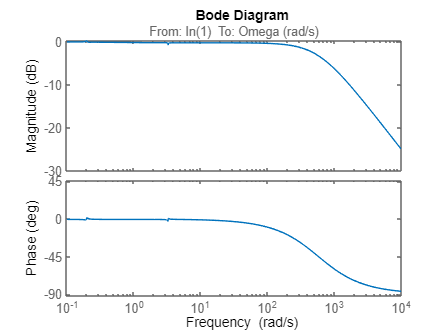



Polecancel = minreal(Plant*C); % To speed up the calculations
fbsys = feedback(Polecancel,1);
bode(fbsys);

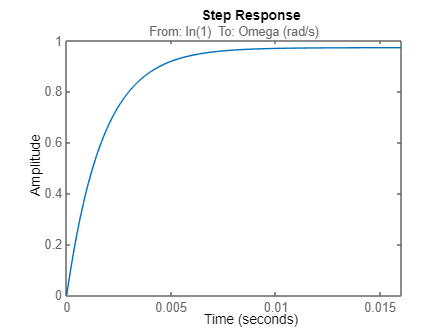

step(fbsys);

stepinfo(fbsys)

ans = struct with fields:
         RiseTime: 0.0043
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.9016
      SettlingMax: 0.9725
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9725
         PeakTime: 0.0530


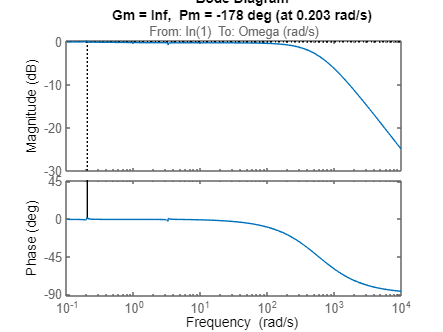

margin(fbsys);

% Try to use notch filter
w1=0.2/(2*pi);
w2=3.3/(2*pi);
beta1 = 1;
beta2 = 10;
beta3 = 1;
beta4 = 10;

num1 = [1,w1*beta1,w1^2];
den1 = [1, w1*beta2,w1^2];
num2 = [1,w2*beta3,w2^2];
den2 = [1, w2*beta3,w2^2];

C_notch1 = tf(num1,den1);
C_notch2 = tf(num2,den2);

% Extra pid
Kp = 1

Kp = 1

Ki = 1

Ki = 1

Kd = 1

Kd = 1

Tf=0.06

Tf = 0.0600

K = pid(Kp, Ki, Kd, Tf)

K =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 1, Ki = 1, Kd = 1, Tf = 0.06
 
Continuous-time PIDF controller in parallel form.




PoleCancel = minreal(Plant*C_notch1*C_notch2)

2 states removed.

PoleCancel =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7
   x1     -0.422    -0.2204          0    -0.2204          0    0.04577          0
   x2    0.02328   -0.01085      -0.04  -0.009574          0   0.003852          0
   x3          0          1          0          0          0          0          0
   x4     0.1455   -0.05984          0    -0.1651     -10.82    0.02407          0
   x5          0          0          0          1          0          0          0
   x6          0          0          0          0          0    -0.3183   -0.03242
   x7          0          0          0          0          0    0.03125          0
 
  B = 
              u1
   x1   -0.07988
   x2  -0.006722
   x3          0
   x4   -0.04202
   x5          0
   x6        0.5
   x7          0
 
  C = 
                 x1  x2  x3  x4  x5  x6  x7
   Omega (rad/s  -1   0   0   0   0   0   0
 
  D = 
                 u1
   Omega (rad/s   0
 
Co

sys_cl = feedback(PoleCancel,1);

bode(sys_cl)

margin(sys_cl)

[y,t] = step(sys_cl);
step(sys_cl);

stepinfo(sys_cl);
sserror=abs(1-y(end))

sserror = 0.8414